# Opgave 1:

Informationer:

- Massen loddet, $m_L = 100 kg$

- Tyngdeaccelerationen, $g = 9.81 \frac{m}{s^2}$

- Fjederkostant, $k_A = 12 \frac{kN}{m}$

- Fjederkonstant, $k_B = 15 \frac{kN}{m}$

- Billedet ses fra hvile, $v_0 = 0 \frac{m}{s}$

- Afstanden, $RA = 0.75 m$

### ***Underopgave 1.A: Tiden fra loddet frigøres til opnår kontakt med fjeder A:***

Da loddet slippes fra hvile, så er kan tiden findes som:

- 
$$s = s_{0} + v_{0}*t+\frac{1}{2}*a*t^2 \\ \rightarrow \\ 
0.75 m = \frac{1}{2}*9.81 \frac{m}{s^2}*t^2 \\ \rightarrow \\
t = 0.391031$$


syms t;
RA = 0.75;
g = 9.81;

vpa(solve(RA == 1/2 * g * t^2,t),6);

### ***Underopgave 1.B: Loddets hastighed ved kontakt med fjeder A:***

Vores lod er 0.391031 sekunder om at komme i kontakt med fjeder A.

Da loddet droppes fra hvile er der intet hastighedsbidrag udover tyngdeaccelerationen:

- 
$$v = v_0 + a \cdot t \\ \rightarrow \\ v = 0 + 9.81 \frac{m}{s^2} \cdot 0.391031 sec \\ \rightarrow \\ v = 3.836 \frac{m}{s}$$


clear all
t = 0.391031;
g = 9.81;
v_0 = 0;

v = v_0 + g * t;

### ***Underopgave 1.C: Loddets kinetiske energi ved kontakt med fjeder A:***

Den kinetiske energi er angivet som:

- 
$$T = \frac{1}{2} \cdot m \cdot v^2 \\ \rightarrow \\ T = 0.5 \cdot 100 kg \cdot (3.836 \frac{m}{s^2})^2 \\ \rightarrow T = 735.74 J$$


clear all
m = 100;
g = 9.81;
v = 3.836;

T = 1/2 * m * v^2;

### ***Underopgave 1.D: Loddets bevægelsesmængde ved kontakt med fjeder A:***

Bevægelsesmængden er angivet som:

- 
$$G = m \cdot \hat{v} \\ \rightarrow \\ G = 100 kg \cdot 3.836 \frac{m}{s} \\ \rightarrow \\ G = 383.6 \, kg \cdot \frac{m}{s}$$


clear all
m = 100;
v = 3.836;

G = m * v;

# Opgave 2:

Informationer:

- Rammen skal rotere om A.

- Vi betragter rammen fra hvile, $v_0 = 0$.

- Rammen vejer $2 \frac{kg}{m}$

- Rammen er $3 \cdot 1.5 m$

- Rammen er en formet som en slanke.

- Tyngdeaccelerationen er  $g = 9.81 \frac{m}{s^2}$

### ***Underopgave 2.A: Rammens masse***

Rammen har en samlet længde på 4.5 meter.

Hertil er det oplyst, at rammen vejer 2 kg pr. meter.

- 
$$m_R = 2 \frac{kg}{m} \cdot 4.5 m = 9 \, kg$$


### ***Underopgave 2.B: Tyngdepunktets position samt en skitse***

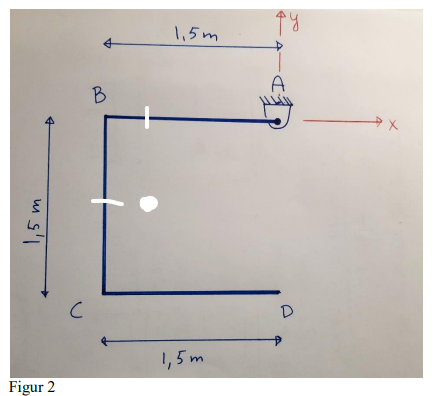

Ser man på det opsatte koordinat system, så har tyngdepunktet koordinaterne (-1, -0.75)

### ***Underopgave 2.C: Masseinertimomentet om A***

Masseinertimomentet om en aksel for en slanke er givet som:

- 
$$I = \frac{1}{3} \cdot m \cdot l^2$$


Da vores ramme er opbygget af 3 slanker, så kan vi omskrive $I$ til:

- 
$$I_A = 3 \cdot (\frac{1}{3} \cdot m \cdot l^2) \\ \rightarrow \\ I_A = 20.25 \, kg \cdot m^2$$


b = 1.5;
l = 1.5;

I_G = 3*((1/3) * 9 * 1.5^2)

I_G = 20.2500

### ***Underopgave 2.D: Frit legeme diagram og kinetisk diagram***

Tegnet i hånden.

### ***Underopgave 2.E: Vinkelaccelerationen***

Til fuldførslen af opgaven skal vi kende:

- Buelængden.

- Theta mellem hvile og center.

DETTE SVAR ER FORKERT!

A = 1;
B = 0.75;
C = sqrt(A^2 + B^2)

C = 1.2500


theta = asind(B/C)

theta = 36.8699


arc = 2*pi * C * (theta/360);

hastigheden = sqrt(9.81/arc)

hastigheden = 3.4922


omega = hastigheden/arc

omega = 4.3416

# Opgave 3:

Informationer:

- Fjederstivheden = 20 N/m

- Dæmpningskoefficienten = 10 N * s/m

- Massen = 10 kg

- F_0 = 100 N

- x_0 = 0.

- v_0 = 0.

### ***Underopgave 3.A: ****Den normerede bevægelsesligning, ligningen ønskes opskrevet symbolsk*

- 
$$m \cdot \ddot{x} + c \cdot \dot{x} + k \cdot x = 0$$
 

### ***Underopgave 3.B: Egenfrekvensen, ***$\omega_n$

Egenfrekvensen er angivet som:

- 
$$\omega_n = \sqrt{\frac{k}{m}}$$


Heraf bliver egenfrekvensen:

- 
$$\omega_n = \sqrt{\frac{20 N}{10 kg}} = 1.4142 Rad$$


k = 20;
m = 10;
omega_n = sqrt(k/m)

omega_n =        1.4142


### ***Underopgave 3.C: ****Dæmpningsforholdet ζ og afgør typen af dæmpning*

Dæmpningsforholdet er angivet som:

- 
$$\zeta = \frac{c}{2 \cdot m \cdot \omega_n} = 0.0112$$


Da zeta er under 1, så er vores system underdæmpet.

clear all
omega_n = 1.4142;
m = 10;
c = 10;

zeta_brug = 0;
zeta = c/(2*m*omega_n);
if zeta < 1
    zeta_brug = zeta
    display("SYSTEMET ER UNDER DÆMPET!");
elseif zeta == 1
    zeta_brug = zeta
    display("SYSTEMET ER KRITISK DÆMPET!");
elseif zeta > 1
    zeta_brug = zeta
    display("SYSTEMET ER OVER DÆMPET!");
end

zeta_brug =       0.35356


    "SYSTEMET ER UNDER DÆMPET!"



### ***Underopgave 3.D: Den dæmpede egenfrekvens ***$\omega_d$

Den dæmpede egenfrekvens er angivet som:

- 
$$\omega_d = \omega_n * \sqrt{1-\zeta^2} = 1.3229$$


clear all;
omega_n = 1.4142;
zeta = 0.35356;

omega_d = omega_n * sqrt(1-zeta^2)

omega_d =        1.3229


### ***Underopgave 3.E: ****Vis at xp(t) = F0/k er en partikulær løsning til bevægelsesligningen*